Define coefficient of Z,X1 and X2.

c = [2; 1];
A = [1, 2; 1, 1; 1, -1; 1, -2];
b = [10; 6; 2; 1];


Create a grid of points for visualization

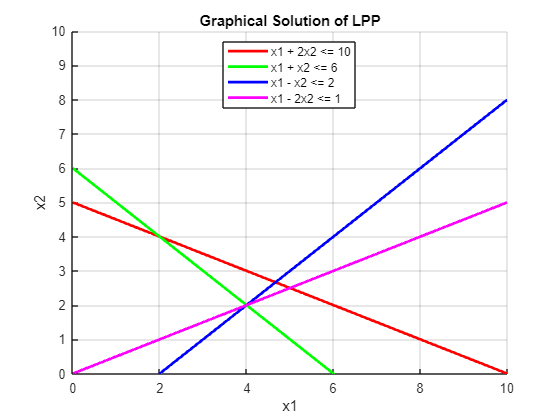

x1 = 4;
x2 = 4.7;

points = length(X1);
feasible_point = zeros(1, points);
Z = zeros(size(X1));


for i = 1:points
    for j = 1:size(A, 1)
        if (A(j, :) * [X1(i), X2(i)]' <= b(j))
            feasible_point(i) = 1;
            break; 
        end
    end
    Z(i) = c(1) * X1(i) + c(2) * X2(i);
end

figure;
hold on;
plot(x1_range, (10 - x1_range) / 2, 'r', 'LineWidth', 2);
plot(x1_range, 6 - x1_range, 'g', 'LineWidth', 2);
plot(x1_range, x1_range - 2, 'b', 'LineWidth', 2);
plot(x1_range, x1_range / 2, 'm', 'LineWidth', 2);

grid on;
ylim([0 10]);
xlabel('x1');
ylabel('x2');
title('Graphical Solution of LPP');

legend('x1 + 2x2 <= 10', 'x1 + x2 <= 6', 'x1 - x2 <= 2', 'x1 - 2x2 <= 1', 'Location', 'best');